# **Modern Control Project : Paper Report**

## **S.Mehdi Moosaviun**

## **ID:99413136**

#### **paper-link : **[(PDF) LQR hybrid approach control of a robotic arm two degrees of freedom (researchgate.net)](https://www.researchgate.net/publication/309049623_LQR_hybrid_approach_control_of_a_robotic_arm_two_degrees_of_freedom)

**---------------------------------------------------------------------------------------------------------------------------------------**

**Question-3 : ** Get a state space view for the system? Introduce state variables. If the system state space model is nonlinear, make it linear.

theta1 = 0.062402;
theta2 = 0.054284;
theta3 = 0.025912;
theta4 = 0.80278;
theta5 = 0.31406;

A_up = [0 1 0 0;
        0 0 108.69545 -112.387;
        0 0 0 1;
        0 -24.959145 85.0663 0];

B_up = [0; 13.930735; 0; -20.58139];

A_mid = [0 1 0 0;
         0 0 -108.69545 105.039;
         0 0 0 1;
         0 24.959145 35.148095 0];

B_mid = [0; 13.9307; 0; -7.281015];

sys_up = ss(A_up, B_up, eye(4), zeros(4,1));
sys_mid = ss(A_mid, B_mid, eye(4), zeros(4,1));

disp('System for Up position:');

System for Up position:


sys_up

sys_up =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0   108.7  -112.4
   x3       0       0       0       1
   x4       0  -24.96   85.07       0
 
  B = 
           u1
   x1       0
   x2   13.93
   x3       0
   x4  -20.58
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.




disp('System for Middle position:');

System for Middle position:


sys_mid

sys_mid =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0  -108.7     105
   x3       0       0       0       1
   x4       0   24.96   35.15       0
 
  B = 
           u1
   x1       0
   x2   13.93
   x3       0
   x4  -7.281
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.




disp('Eigenvalues for Up position:');

Eigenvalues for Up position:


eig(A_up)

ans =          0
  -54.2234
   53.2845
    0.9390



disp('Eigenvalues for Middle position:');

Eigenvalues for Middle position:


eig(A_mid)

ans =          0
  -52.0476
   51.0261
    1.0215


**Question-4 :**  Check the controllability and visibility of the display of the obtained state space? Is it possible to design a mode feedback and mode estimator for this show? If the resulting state space display is uncontrollable, separate it into controllable and uncontrollable subsystems. Also, if the display of the obtained state space is invisible, separate it into visible and invisible subsystems. 

disp('Controllability and Observability Analysis:');

Controllability and Observability Analysis:



disp('Up position:');

Up position:



Mc_up = ctrb(A_up, B_up);
rank_Mc_up = rank(Mc_up);
disp(['Rank of controllability matrix (Up): ', num2str(rank_Mc_up)]);

Rank of controllability matrix (Up): 4


if rank_Mc_up == size(A_up, 1)
    disp('The system is controllable (Up)');
else
    disp('The system is not controllable (Up)');
end

The system is controllable (Up)



Mo_up = obsv(A_up, eye(4));
rank_Mo_up = rank(Mo_up);
disp(['Rank of observability matrix (Up): ', num2str(rank_Mo_up)]);

Rank of observability matrix (Up): 4


if rank_Mo_up == size(A_up, 1)
    disp('The system is observable (Up)');
else
    disp('The system is not observable (Up)');
end

The system is observable (Up)



disp('Middle position:');

Middle position:



Mc_mid = ctrb(A_mid, B_mid);
rank_Mc_mid = rank(Mc_mid);
disp(['Rank of controllability matrix (Middle): ', num2str(rank_Mc_mid)]);

Rank of controllability matrix (Middle): 4


if rank_Mc_mid == size(A_mid, 1)
    disp('The system is controllable (Middle)');
else
    disp('The system is not controllable (Middle)');
end

The system is controllable (Middle)



Mo_mid = obsv(A_mid, eye(4)); 
rank_Mo_mid = rank(Mo_mid);
disp(['Rank of observability matrix (Middle): ', num2str(rank_Mo_mid)]);

Rank of observability matrix (Middle): 4


if rank_Mo_mid == size(A_mid, 1)
    disp('The system is observable (Middle)');
else
    disp('The system is not observable (Middle)');
end

The system is observable (Middle)


**Question-5** **:**  If the state space representation obtained in the previous episode is not minimal, get a minimum state space representation for the system?

C_up = eye(4);
[A_min_up, B_min_up, C_min_up] = minimal_realization(A_up, B_up, C_up);

C_mid = eye(4); 
[A_min_mid, B_min_mid, C_min_mid] = minimal_realization(A_mid, B_mid, C_mid);

disp('Minimal Realization for Up position:');

Minimal Realization for Up position:


disp('A_min_up:');

A_min_up:


disp(A_min_up);

   17.3368 -109.9351   -7.6333  -96.2077
  -23.3995  -18.2759  -11.6135  -97.8676
    0.0001    0.0001    0.4203    3.3717
    0.0000    0.0000    0.0647    0.5188



disp('B_min_up:');

B_min_up:


disp(B_min_up);

  -16.5549
   18.5186
   -0.7773
    0.2288



disp('C_min_up:');

C_min_up:


disp(C_min_up);

   -0.0052    0.0385    0.9916   -0.1236
   -0.9910   -0.1337    0.0011    0.0088
    0.0089    0.0009    0.1237    0.9923
    0.1336   -0.9903    0.0385   -0.0051




disp('Minimal Realization for Middle position:');

Minimal Realization for Middle position:


disp('A_min_mid:');

A_min_mid:


disp(A_min_mid);

  -50.1129   81.9814  -61.0193   95.6491
    2.3865   49.0901   -6.2201   12.1109
   -0.0004   -0.0090    0.9757   -1.4236
    0.0000    0.0003   -0.0323    0.0471



disp('B_min_mid:');

B_min_mid:


disp(B_min_mid);

   15.6940
   -0.8224
   -0.3106
   -0.0556



disp('C_min_mid:');

C_min_mid:


disp(C_min_mid);

   -0.0164    0.0358   -0.8241   -0.5650
    0.9094    0.4159   -0.0055    0.0079
    0.0085    0.0044    0.5655   -0.8247
   -0.4156    0.9087    0.0322    0.0227




disp('Eigenvalues for Minimal Up position:');

Eigenvalues for Minimal Up position:


eig(A_min_up)

ans =    53.2845
  -54.2234
    0.9390
    0.0000


disp('Eigenvalues for Minimal Middle position:');

Eigenvalues for Minimal Middle position:


eig(A_min_mid)

ans =   -52.0476
   51.0261
    1.0215
    0.0000



sys_min_up = ss(A_min_up, B_min_up, C_min_up, 0);
sys_min_mid = ss(A_min_mid, B_min_mid, C_min_mid, 0);

disp('Minimal System for Up position:');

Minimal System for Up position:


sys_min_up

sys_min_up =
 
  A = 
              x1         x2         x3         x4
   x1      17.34     -109.9     -7.633     -96.21
   x2      -23.4     -18.28     -11.61     -97.87
   x3  0.0001237  0.0001017     0.4203      3.372
   x4  1.903e-05  1.565e-05    0.06467     0.5188
 
  B = 
            u1
   x1   -16.55
   x2    18.52
   x3  -0.7773
   x4   0.2288
 
  C = 
              x1         x2         x3         x4
   y1  -0.005186    0.03851     0.9916    -0.1236
   y2     -0.991    -0.1337   0.001112   0.008831
   y3   0.008865  0.0008599     0.1237     0.9923
   y4     0.1336    -0.9903    0.03852  -0.005138
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



disp('Minimal System for Middle position:');

Minimal System for Middle position:


sys_min_mid

sys_min_mid =
 
  A = 
               x1          x2          x3          x4
   x1      -50.11       81.98      -61.02       95.65
   x2       2.387       49.09       -6.22       12.11
   x3  -0.0004487   -0.009035      0.9757      -1.424
   x4   1.484e-05   0.0002989    -0.03228     0.04709
 
  B = 
             u1
   x1     15.69
   x2   -0.8224
   x3   -0.3106
   x4  -0.05561
 
  C = 
              x1         x2         x3         x4
   y1   -0.01644    0.03577    -0.8241     -0.565
   y2     0.9094     0.4159  -0.005468   0.007854
   y3   0.008499   0.004427     0.5655    -0.8247
   y4    -0.4156     0.9087    0.03219    0.02267
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.



**Question-6** **:  **To display the resulting state space for the system, design the state feedback so that the poles of the closed-loop system are positioned in the desired locations on the left side of the Jω axis. Plot the step response and system state variables. Compare the poles and zeros of the closed-loop and open-loop system. 

 Note: Perform this step to locate the near and far poles and compare the control signal and the feedback gain obtained in both modes.

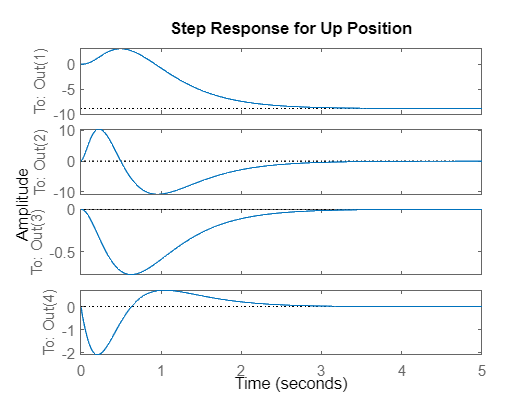

A_up = [0 1 0 0;
        0 0 108.69545 -112.387;
        0 0 0 1;
        0 -24.959145 85.0663 0];

B_up = [0; 13.930735; 0; -20.58139];

A_mid = [0 1 0 0;
         0 0 -108.69545 105.039;
         0 0 0 1;
         0 24.959145 35.148095 0];

B_mid = [0; 13.9307; 0; -7.281015];

% Open loop systems
sys_up = ss(A_up, B_up, eye(4), zeros(4,1));
sys_mid = ss(A_mid, B_mid, eye(4), zeros(4,1));

% Pole placement for Up position
p_up = [-2 -4 -6 -8]; 
K_up = place(A_up, B_up, p_up);
A_fb_up = A_up - B_up * K_up;
sys_fb_up = ss(A_fb_up, B_up, eye(4), zeros(4,1));

% Pole placement for Middle position
p_mid = [-2 -4 -6 -8]; 
K_mid = place(A_mid, B_mid, p_mid);
A_fb_mid = A_mid - B_mid * K_mid;
sys_fb_mid = ss(A_fb_mid, B_mid, eye(4), zeros(4,1));

% Open loop poles
open_loop_pole_up = pole(sys_up);
open_loop_pole_mid = pole(sys_mid);

% Closed loop poles
close_loop_pole_up = pole(sys_fb_up);
close_loop_pole_mid = pole(sys_fb_mid);

% Step response for Up position
figure;
step(sys_fb_up);
title('Step Response for Up Position');


disp('----------------------------------------------------------------------------------------------------')

----------------------------------------------------------------------------------------------------


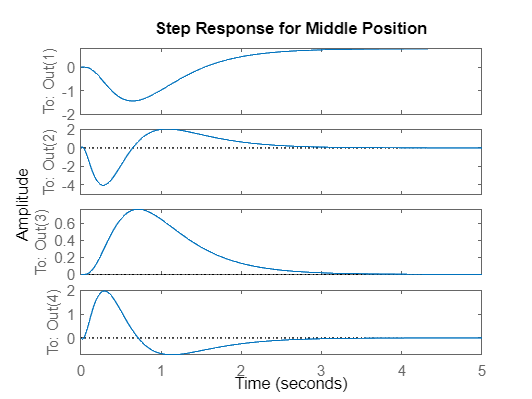

% Step response for Middle position
figure;
step(sys_fb_mid);
title('Step Response for Middle Position');


% State variables over time
t = 0:0.01:5;
x_up = zeros(4, length(t));
x_mid = zeros(4, length(t));

% Simulate state responses
for i = 2:length(t)
    x_up(:, i) = x_up(:, i-1) + 0.01 * (A_fb_up * x_up(:, i-1) + B_up);
    x_mid(:, i) = x_mid(:, i-1) + 0.01 * (A_fb_mid * x_mid(:, i-1) + B_mid);
end

disp('----------------------------------------------------------------------------------------------------')

----------------------------------------------------------------------------------------------------


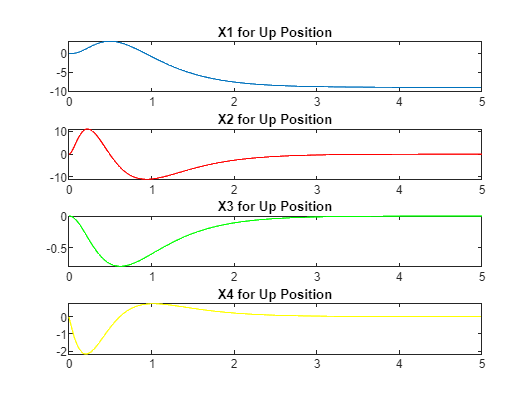


figure;
    subplot(4, 1, 1);
        plot(t, x_up(1, :));
        title('X1 for Up Position');
    subplot(4, 1, 2);
        plot(t, x_up(2, :), 'r');
        title('X2 for Up Position');
    subplot(4, 1, 3);
        plot(t, x_up(3, :), 'g');
        title('X3 for Up Position');
    subplot(4, 1, 4);
        plot(t, x_up(4, :), 'y');
        title('X4 for Up Position');


disp('----------------------------------------------------------------------------------------------------')

----------------------------------------------------------------------------------------------------


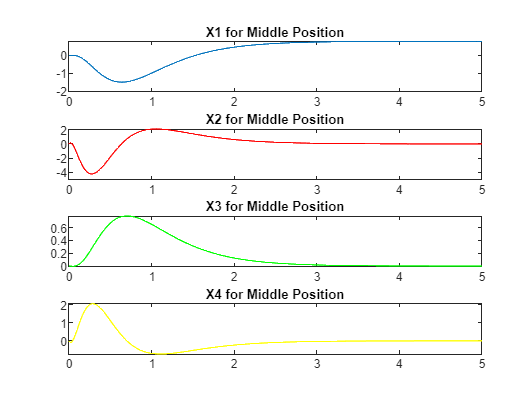


figure;
    subplot(4, 1, 1);
        plot(t, x_mid(1, :));
        title('X1 for Middle Position');
    subplot(4, 1, 2);
        plot(t, x_mid(2, :), 'r');
        title('X2 for Middle Position');
    subplot(4, 1, 3);
        plot(t, x_mid(3, :), 'g');
        title('X3 for Middle Position');
    subplot(4, 1, 4);
        plot(t, x_mid(4, :), 'y');
        title('X4 for Middle Position');



disp('Open Loop Poles for Up Position:');

Open Loop Poles for Up Position:


disp(open_loop_pole_up);

         0
  -54.2234
   53.2845
    0.9390



disp('Closed Loop Poles for Up Position:');

Closed Loop Poles for Up Position:


disp(close_loop_pole_up);

   -8.0000
   -6.0000
   -4.0000
   -2.0000




disp('Open Loop Poles for Middle Position:');

Open Loop Poles for Middle Position:


disp(open_loop_pole_mid);

         0
  -52.0476
   51.0261
    1.0215



disp('Closed Loop Poles for Middle Position:');

Closed Loop Poles for Middle Position:


disp(close_loop_pole_mid);

   -8.0000
   -6.0000
   -4.0000
   -2.0000



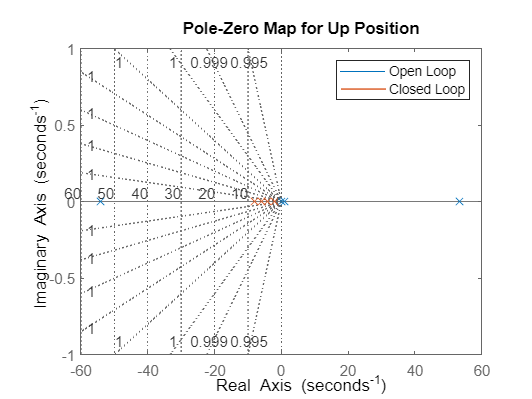



figure;
    pzmap(sys_up);
        hold on;
    pzmap(sys_fb_up);
        title('Pole-Zero Map for Up Position');
        legend('Open Loop', 'Closed Loop');
        grid on

disp('----------------------------------------------------------------------------------------------------')

----------------------------------------------------------------------------------------------------


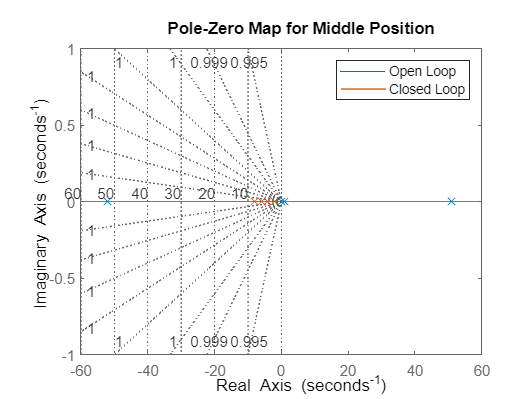


figure;
    pzmap(sys_mid);
        hold on;
    pzmap(sys_fb_mid);
        title('Pole-Zero Map for Middle Position');
        legend('Open Loop', 'Closed Loop');
        grid on

**Question-7 :  **Design a static tracker for the system under review. Evaluate the performance of this detector against the presence of various disturbances and uncertainties in the system model.

A_up = [0 1 0 0;
        0 0 108.69545 -112.387;
        0 0 0 1;
        0 -24.959145 85.0663 0];

B_up = [0; 13.930735; 0; -20.58139];

C_up = eye(4);
D_up = zeros(4, 1);

% Desired pole locations for Up position
p_up = [-2 -4 -6 -8];
K_up = place(A_up, B_up, p_up);
A_fb_up = A_up - B_up * K_up;

% Static state feedback tracker design
P_up = pinv(C_up * inv(-A_fb_up) * B_up)

P_up =    -0.1122         0         0         0


B_st_up = B_up * P_up

B_st_up =          0         0         0         0
   -1.5632         0         0         0
         0         0         0         0
    2.3094         0         0         0


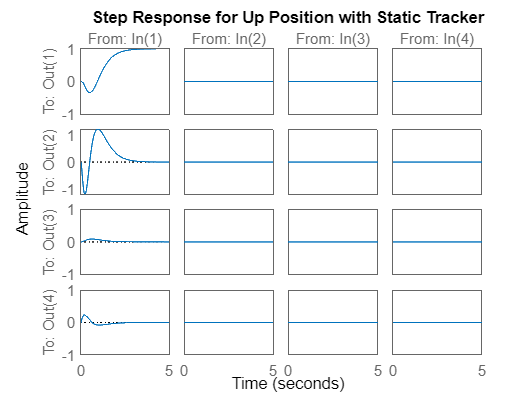


% Adjust D_up to have the same number of columns as B_st_up
D_up = zeros(size(C_up, 1), size(B_st_up, 2));

% State-space system with state feedback
sys_fb_st_up = ss(A_fb_up, B_st_up, C_up, D_up);

% Simulation parameters
t = 0:0.01:5;
x_st_up = zeros(4, length(t));

% Simulate state responses with static tracker
for i = 2:length(t)
    x_st_up(:, i) = x_st_up(:, i-1) + 0.01 * (A_fb_up * x_st_up(:, i-1) + B_st_up(:, 1));
end


figure;
step(sys_fb_st_up);
title('Step Response for Up Position with Static Tracker');


disp('----------------------------------------------------------------------------------------------------')

----------------------------------------------------------------------------------------------------


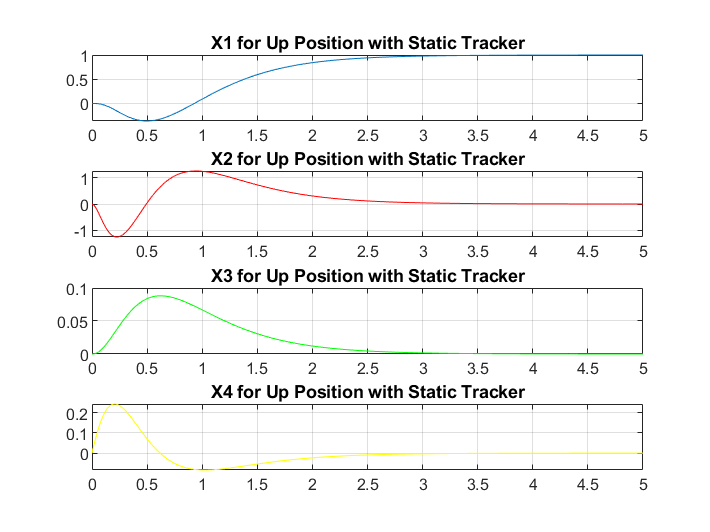


figure;
subplot(4, 1, 1);
plot(t, x_st_up(1, :));
title('X1 for Up Position with Static Tracker');
subplot(4, 1, 2);
plot(t, x_st_up(2, :), 'r');
title('X2 for Up Position with Static Tracker');
subplot(4, 1, 3);
plot(t, x_st_up(3, :), 'g');
title('X3 for Up Position with Static Tracker');
subplot(4, 1, 4);
plot(t, x_st_up(4, :), 'y');
title('X4 for Up Position with Static Tracker');

subplot(4,1,1)
grid on
subplot(4,1,2)
grid on
subplot(4,1,3)
grid on
subplot(4,1,4)
grid on


% Evaluate performance in presence of disturbances
% Adding disturbances to the system
disturbance = [0.1; 0.05; 0.1; 0.05]; 
x_dist_up = zeros(4, length(t));

for i = 2:length(t)
    x_dist_up(:, i) = x_dist_up(:, i-1) + 0.01 * (A_fb_up * x_dist_up(:, i-1) + B_st_up(:, 1) + disturbance);
end

disp('----------------------------------------------------------------------------------------------------')

----------------------------------------------------------------------------------------------------


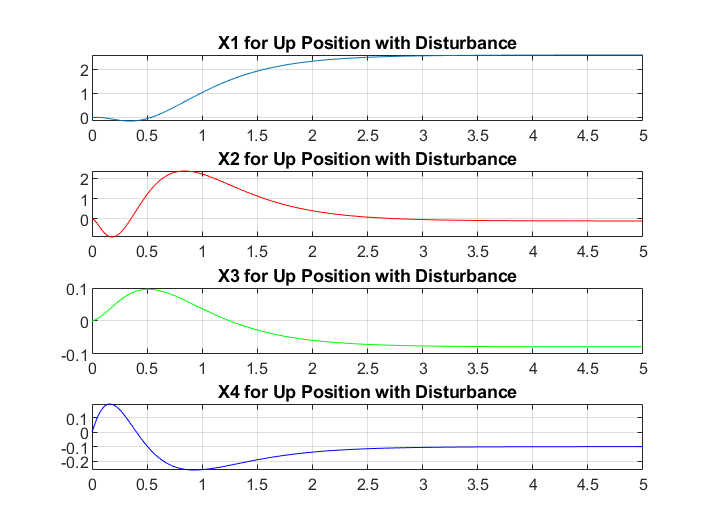

figure;
subplot(4, 1, 1);
plot(t, x_dist_up(1, :));
title('X1 for Up Position with Disturbance');
subplot(4, 1, 2);
plot(t, x_dist_up(2, :), 'r');
title('X2 for Up Position with Disturbance');
subplot(4, 1, 3);
plot(t, x_dist_up(3, :), 'g');
title('X3 for Up Position with Disturbance');
subplot(4, 1, 4);
plot(t, x_dist_up(4, :), 'b');
title('X4 for Up Position with Disturbance');

subplot(4,1,1)
grid on
subplot(4,1,2)
grid on
subplot(4,1,3)
grid on
subplot(4,1,4)
grid on


% Evaluate performance in presence of model uncertainty
% Adding model uncertainty to the system
A_uncertain_up = A_fb_up + 0.05 * randn(size(A_fb_up)); 

x_uncertain_up = zeros(4, length(t));

for i = 2:length(t)
    x_uncertain_up(:, i) = x_uncertain_up(:, i-1) + 0.01 * (A_uncertain_up * x_uncertain_up(:, i-1) + B_st_up(:, 1));
end

disp('----------------------------------------------------------------------------------------------------')

----------------------------------------------------------------------------------------------------


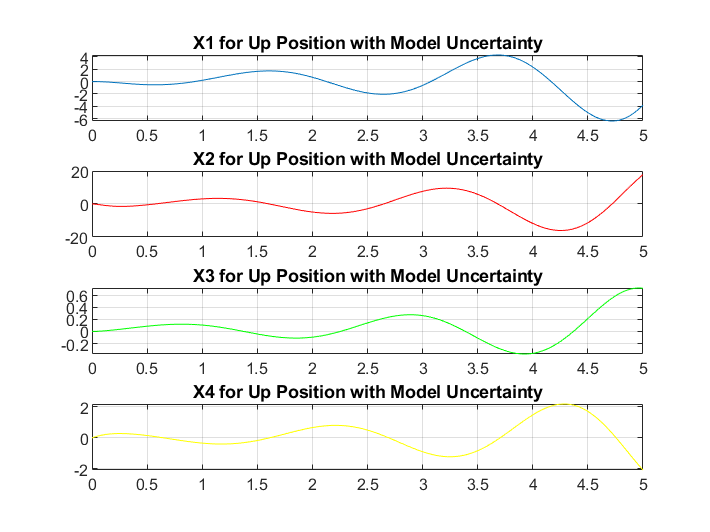

figure;
subplot(4, 1, 1);
plot(t, x_uncertain_up(1, :));
title('X1 for Up Position with Model Uncertainty');
subplot(4, 1, 2);
plot(t, x_uncertain_up(2, :), 'r');
title('X2 for Up Position with Model Uncertainty');
subplot(4, 1, 3);
plot(t, x_uncertain_up(3, :), 'g');
title('X3 for Up Position with Model Uncertainty');
subplot(4, 1, 4);
plot(t, x_uncertain_up(4, :), 'y');
title('X4 for Up Position with Model Uncertainty');

subplot(4,1,1)
grid on
subplot(4,1,2)
grid on
subplot(4,1,3)
grid on
subplot(4,1,4)
grid on

**Question-8 :**  Design an integral tracker for the system under consideration. Evaluate the performance of this detector against the presence of various disturbances and uncertainties in the system model.

A_up = [0 1 0 0;
        0 0 108.69545 -112.387;
        0 0 0 1;
        0 -24.959145 85.0663 0];

B_up = [0; 13.930735; 0; -20.58139];

C_up = eye(4);
D_up = zeros(4, 1);

% Check controllability of the original system
Mc_up = ctrb(A_up, B_up);
if rank(Mc_up) == size(A_up, 1)
    disp('Original system is controllable');
else
    disp('Original system is not controllable');
    return; % Exit the script if the system is not controllable
end

Original system is controllable



% Check integral controllability
n = size(A_up, 1); % Number of states
m = size(C_up, 1); % Number of outputs

augmented_matrix = [B_up, A_up; zeros(m, 1), C_up];
if rank(augmented_matrix) == n + m
    disp('System is integrally controllable');
else
    disp('System is not integrally controllable');
    return; % Exit the script if the system is not integrally controllable
end

System is not integrally controllable



% Augmented system for integral control
A_aug = [A_up, zeros(n, m); -C_up, zeros(m, m)];
B_aug = [B_up; zeros(m, 1)];

% Check controllability of augmented system
Mc_aug = ctrb(A_aug, B_aug);
if rank(Mc_aug) == size(A_aug, 1)
    disp('Augmented system is controllable');
else
    disp('Augmented system is not controllable');
    return; % Exit the script if the augmented system is not controllable
end


p_aug = [-2 -4 -6 -8 -10 -12]; 

% State feedback gains for the augmented system
K_aug = place(A_aug, B_aug, p_aug);

% Extract K and Ki from K_aug
K = K_aug(1:n);
Ki = K_aug(n+1:end);

% State-space system with integral control
A_fb_int = [A_up - B_up * K, -B_up * Ki; -C_up, zeros(m, m)];
B_fb_int = [zeros(n, 1); eye(m)];
C_fb_int = [C_up, zeros(m, m)];
D_fb_int = zeros(m, 1);

% Define the system with integral control
sys_fb_int = ss(A_fb_int, B_fb_int, C_fb_int, D_fb_int);

% Simulation parameters
t = 0:0.01:5;
x_int = zeros(n + m, length(t));

% Simulate state responses with integral control
for i = 2:length(t)
    x_int(:, i) = x_int(:, i-1) + 0.01 * (A_fb_int * x_int(:, i-1) + B_fb_int * 1);
end

figure;
step(sys_fb_int);
title('Step Response for Up Position with Integral Control');

figure;
subplot(4, 1, 1);
plot(t, x_int(1, :));
title('X1 for Up Position with Integral Control');
subplot(4, 1, 2);
plot(t, x_int(2, :), 'r');
title('X2 for Up Position with Integral Control');
subplot(4, 1, 3);
plot(t, x_int(3, :), 'g');
title('X3 for Up Position with Integral Control');
subplot(4, 1, 4);
plot(t, x_int(4, :), 'y');
title('X4 for Up Position with Integral Control');

% Evaluate performance in presence of disturbances
% Adding disturbances to the system
disturbance = [0.1; 0.05; 0.1; 0.05]; 

x_dist_int = zeros(n + m, length(t));

for i = 2:length(t)
    x_dist_int(:, i) = x_dist_int(:, i-1) + 0.01 * (A_fb_int * x_dist_int(:, i-1) + B_fb_int * 1 + [disturbance; zeros(m, 1)]);
end

figure;
subplot(4, 1, 1);
plot(t, x_dist_int(1, :));
title('X1 for Up Position with Disturbance');
subplot(4, 1, 2);
plot(t, x_dist_int(2, :), 'r');
title('X2 for Up Position with Disturbance');
subplot(4, 1, 3);
plot(t, x_dist_int(3, :), 'g');
title('X3 for Up Position with Disturbance');
subplot(4, 1, 4);
plot(t, x_dist_int(4, :), 'y');
title('X4 for Up Position with Disturbance');

% Evaluate performance in presence of model uncertainty
% Adding model uncertainty to the system
A_uncertain_int = A_fb_int + 0.05 * randn(size(A_fb_int)); 

x_uncertain_int = zeros(n + m, length(t));

for i = 2:length(t)
    x_uncertain_int(:, i) = x_uncertain_int(:, i-1) + 0.01 * (A_uncertain_int * x_uncertain_int(:, i-1) + B_fb_int * 1);
end

figure;
subplot(4, 1, 1);
plot(t, x_uncertain_int(1, :));
title('X1 for Up Position with Model Uncertainty');
subplot(4, 1, 2);
plot(t, x_uncertain_int(2, :), 'r');
title('X2 for Up Position with Model Uncertainty');
subplot(4, 1, 3);
plot(t, x_uncertain_int(3, :), 'g');
title('X3 for Up Position with Model Uncertainty');
subplot(4, 1, 4);
plot(t, x_uncertain_int(4, :), 'y');
title('X4 for Up Position with Model Uncertainty');

**Question-9 :**  To show the obtained state space for the system, design a full-order estimator. What is the criterion for selecting the estimating poles of the state, plot the variables of the main and estimated state of the system and the estimation error.

A_up = [0 1 0 0;
        0 0 108.69545 -112.387;
        0 0 0 1;
        0 -24.959145 85.0663 0];

B_up = [0; 13.930735; 0; -20.58139];

C_up = eye(4);
D_up = zeros(4, 1);

K = place(A_up, B_up, [-1, -2, -3, -4]);
A_stable = A_up - B_up * K;

P_slow = [-1.5, -2.5, -3.5, -4.5];
L_slow = place(A_stable', C_up', P_slow)'

L_slow =     1.5000    1.0000         0         0
    0.0977  -15.2958  177.8041 -117.6637
         0         0    3.5000    1.0000
   -0.1443    1.3326  -17.0354   12.2958



P_fast = [-5, -6, -7, -8];
L_fast = place(A_stable', C_up', P_fast)'

L_fast =     5.0000    1.0000         0         0
    0.0977  -11.7958  177.8041 -117.6637
         0         0    7.0000    1.0000
   -0.1443    1.3326  -17.0354   15.7958


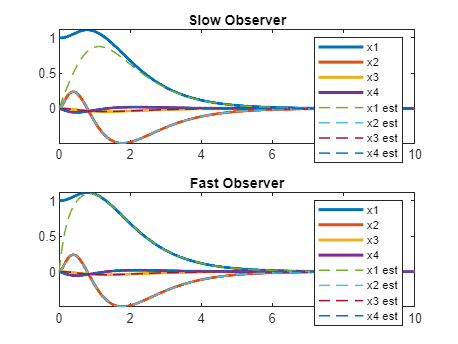


t = 0:0.01:10;
x0 = [1; 0; 0; 0];
x0_est = [0; 0; 0; 0];

[t, x_slow] = ode45(@(t, x) observer_dynamics(t, x, A_stable, B_up, C_up, L_slow, K), t, [x0; x0_est]);

[t, x_fast] = ode45(@(t, x) observer_dynamics(t, x, A_stable, B_up, C_up, L_fast, K), t, [x0; x0_est]);

figure;
subplot(2, 1, 1);
plot(t, x_slow(:, 1:4), 'LineWidth', 2);
hold on;
plot(t, x_slow(:, 5:8), '--', 'LineWidth', 1);
title('Slow Observer');
legend('x1', 'x2', 'x3', 'x4', 'x1 est', 'x2 est', 'x3 est', 'x4 est');

subplot(2, 1, 2);
plot(t, x_fast(:, 1:4), 'LineWidth', 2);
hold on;
plot(t, x_fast(:, 5:8), '--', 'LineWidth', 1);
title('Fast Observer');
legend('x1', 'x2', 'x3', 'x4', 'x1 est', 'x2 est', 'x3 est', 'x4 est');

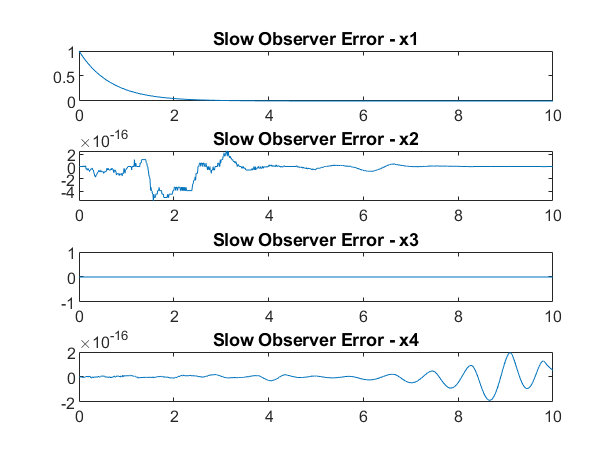


figure;
subplot(4, 1, 1);
plot(t, x_slow(:, 1) - x_slow(:, 5));
title('Slow Observer Error - x1');

subplot(4, 1, 2);
plot(t, x_slow(:, 2) - x_slow(:, 6));
title('Slow Observer Error - x2');

subplot(4, 1, 3);
plot(t, x_slow(:, 3) - x_slow(:, 7));
title('Slow Observer Error - x3');

subplot(4, 1, 4);
plot(t, x_slow(:, 4) - x_slow(:, 8));
title('Slow Observer Error - x4');

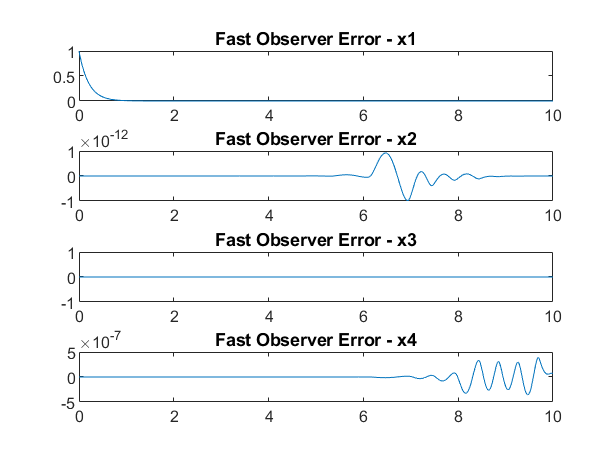


figure;
subplot(4, 1, 1);
plot(t, x_fast(:, 1) - x_fast(:, 5));
title('Fast Observer Error - x1');

subplot(4, 1, 2);
plot(t, x_fast(:, 2) - x_fast(:, 6));
title('Fast Observer Error - x2');

subplot(4, 1, 3);
plot(t, x_fast(:, 3) - x_fast(:, 7));
title('Fast Observer Error - x3');

subplot(4, 1, 4);
plot(t, x_fast(:, 4) - x_fast(:, 8));
title('Fast Observer Error - x4');

**Question-10 : ** To show the obtained state space for the system, design an order reduction estimator. Plot the system's original and estimated state variables and estimation error.

clear all;
clc;

A = [0 1 0 0;
     0 0 108.7 -112.4;
     0 0 0 1;
     0 -24.96 85.07 0];
B = [0; 13.93; 0; -20.58];
C = eye(4); 


P = eye(4);

% Check the rank of P
disp('Rank of P:');

Rank of P:


disp(rank(P));

     4




% Transform the system
Abar = A;
Bbar = B;
Cbar = C;

% Partition the transformed system
A11 = Abar(1, 1);
A12 = Abar(1, 2:end);
A21 = Abar(2:end, 1);
A22 = Abar(2:end, 2:end);
B1 = Bbar(1);
B2 = Bbar(2:end);

% Ensure A22 rank is non-zero
if rank(A22) == 0
    error('Rank of A22 is zero, cannot proceed with observer design.');
end

% Desired poles for the reduced-order observer
P_desire = [-5 -6 -7]; 

% Calculate the observer gain
K = place(A22', A12', P_desire)';
L = K;


disp('Observer gain L:');

Observer gain L:


disp(L);

   18.0000
   -0.2038
  -26.8659



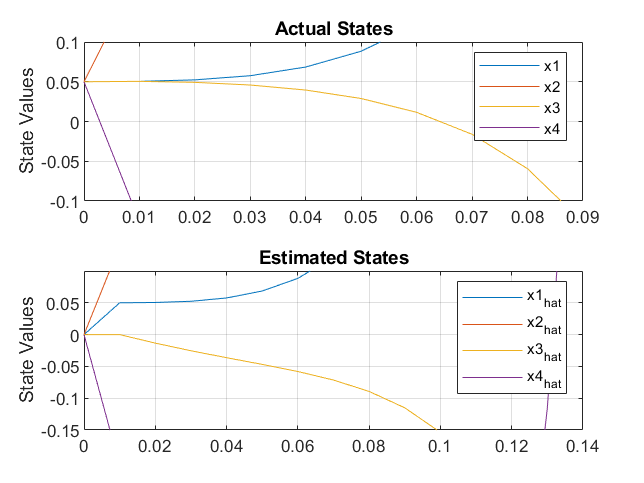


% Initial conditions
xn = [0.05; 0.05; 0.05; 0.05];  
tspan = 0:0.01:5;  
ct = length(tspan);
z = zeros(3, ct);
y = zeros(4, ct);

% Simulate the system
for k = 2:ct
    y(:, k) = Cbar * xn(:, k-1);
    xn(:, k) = xn(:, k-1) + 0.01 * (Abar * xn(:, k-1) + Bbar);
    z(:, k) = z(:, k-1) + 0.01 * ((A22 - L * A12) * z(:, k-1) + ((A22 - L * A12) * L + A21) * y(1, k-1) + (B2 - L * B1));  
end

% Calculate the estimated state
x_hat = [y(1, :); z];


figure;
subplot(2, 1, 1);
plot(tspan, xn);
title('Actual States');
ylabel('State Values');
legend('x1', 'x2', 'x3', 'x4');
ylim([-0.1 0.1]);
grid on;

subplot(2, 1, 2);
plot(tspan, x_hat);
title('Estimated States');
ylabel('State Values');
legend('x1_{hat}', 'x2_{hat}', 'x3_{hat}', 'x4_{hat}');
ylim([-0.15 0.1]);
grid on;

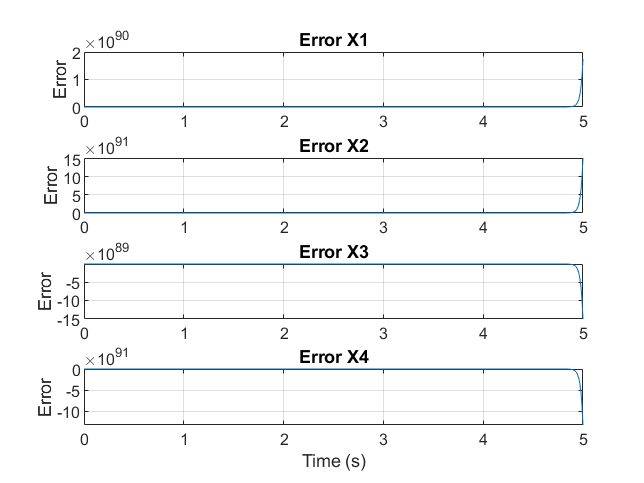


figure;
for i = 1:4
    subplot(4, 1, i);
    plot(tspan, xn(i, :) - x_hat(i, :));
    title(['Error X', num2str(i)]);
    ylabel('Error');
    grid on;
    if i == 4
        xlabel('Time (s)');
    end
end

**Question-11** :  Design the closed-loop system by designing the feedback of the estimated states in such a way that the poles of the closed-loop system are on the left side of the Jω axis and the step response behaves reasonably in terms of leap and landing time. Plot the step response and system state variables. In fact, suppose that the system states are not available and the estimated states should be used for state feedback.

clear all;
clc;

A = [0 1 0 0;
     0 0 108.7 -112.4;
     0 0 0 1;
     0 -24.96 85.07 0];
B = [0; 13.93; 0; -20.58];
C = eye(4);
D = zeros(4,1);

% Design state feedback controller
K = place(A, B, [-5, -6, -7, -8])

K =    -0.4909    1.2013  -10.3522   -0.4502


L = place(A', C', [-50, -60, -70, -80])'

L =    50.0000    1.0000         0         0
         0   60.0000  108.7000 -112.4000
         0         0   70.0000    1.0000
         0  -24.9600   85.0700   80.0000


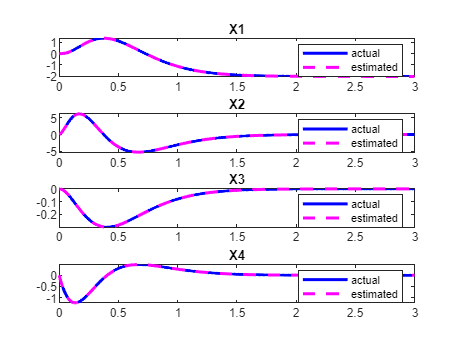


% Augmented system matrices for observer-based state feedback
A_aug = [A - B*K, zeros(4); L*C, A - L*C - B*K];
B_aug = [B; B];
C_aug = [zeros(1,4), C(1,:)];
D_aug = 0;


tspan = linspace(0, 3, 1000);

% Initial conditions
x0 = zeros(8, 1);

% Simulate the augmented system
sys_aug = ss(A_aug, B_aug, C_aug, D_aug);
r = ones(size(tspan)); 
[y_aug, ~, x_aug] = lsim(sys_aug, r, tspan, x0);


figure();
subplot(4,1,1);
plot(tspan, x_aug(:,1), "b", tspan, x_aug(:,5), "magenta--", 'linewidth', 2);
legend("actual", "estimated");
title("X1");

subplot(4,1,2);
plot(tspan, x_aug(:,2), "b", tspan, x_aug(:,6), "magenta--", 'linewidth', 2);
legend("actual", "estimated");
title("X2");

subplot(4,1,3);
plot(tspan, x_aug(:,3), "b", tspan, x_aug(:,7), "magenta--", 'linewidth', 2);
legend("actual", "estimated");
title("X3");

subplot(4,1,4);
plot(tspan, x_aug(:,4), "b", tspan, x_aug(:,8), "magenta--", 'linewidth', 2);
legend("actual", "estimated");
title("X4");

disp('------------------------------------------------------------------------------------------------------------')

------------------------------------------------------------------------------------------------------------


**Question-12** :  Gain the optimal state feedback gain of the system to minimize the following cost function for different values of the R matrix and the Q matrix.

Once assume the matrix Q to be constant and change the matrix R. Compare the simulation results. Once again, consider the matrix R to be fixed and change the matrix Q. Compare the simulation results (behavior of state variables and control signals) in both situations.

clear all;
clc;

A = [0 1 0 0;
     0 0 108.7 -112.4;
     0 0 0 1;
     0 -24.96 85.07 0];
B = [0; 13.93; 0; -20.58];
C = eye(4);
D = zeros(4,1);


x0 = [0.05; 0; 0; 0];


t = linspace(0, 5, 1000);

% Case 1: Varying R with constant Q
Q = eye(4)

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


R_values = [1, 10, 100, 500, 1000, 5000, 10000]

R_values =            1          10         100         500        1000        5000       10000


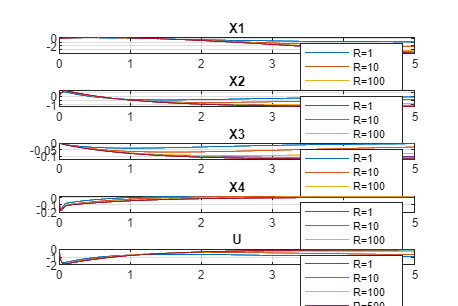


figure('Position', [100, 100, 1200, 800]);

for i = 1:length(R_values)
    R = R_values(i);
    [K,~,P] = lqr(A, B, Q, R);
    sys = ss(A-B*K, B, C, D);
    [y,~,x] = lsim(sys, ones(size(t)), t, x0);
    u = -K * x';

    subplot(5,1,1);
    plot(t, x(:,1), 'DisplayName', ['R=' num2str(R)]);
    title('X1');
    hold on;

    subplot(5,1,2);
    plot(t, x(:,2), 'DisplayName', ['R=' num2str(R)]);
    title('X2');
    hold on;

    subplot(5,1,3);
    plot(t, x(:,3), 'DisplayName', ['R=' num2str(R)]);
    title('X3');
    hold on;

    subplot(5,1,4);
    plot(t, x(:,4), 'DisplayName', ['R=' num2str(R)]);
    title('X4');
    hold on;

    subplot(5,1,5);
    plot(t, u, 'DisplayName', ['R=' num2str(R)]);
    title('U');
    hold on;
end

subplot(5,1,1);
legend();
grid on;

subplot(5,1,2);
legend();
grid on;

subplot(5,1,3);
legend();
grid on;

subplot(5,1,4);
legend();
grid on;

subplot(5,1,5);
legend();
grid on;


disp('------------------------------------------------------------------------------------------------------------')

------------------------------------------------------------------------------------------------------------


% Case 2: Varying Q with constant R
R = 1

R = 1

Q_values = {eye(4), 10*eye(4), 50*eye(4), 100*eye(4), 500*eye(4), 1000*eye(4), 5000*eye(4)}

Q_values = 1×7 cell array
    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}    {4×4 double}


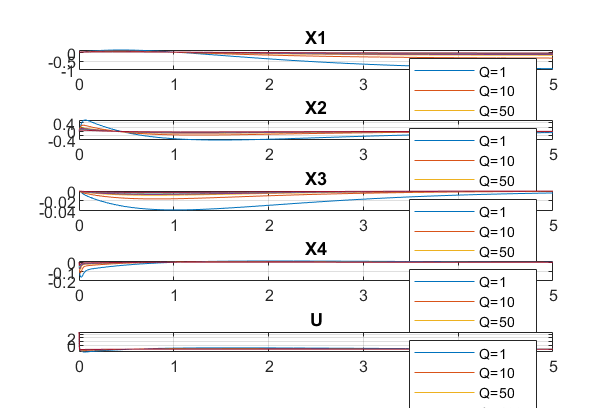


figure('Position', [100, 100, 1200, 800]);

for i = 1:length(Q_values)
    Q = Q_values{i};
    [K,~,P] = lqr(A, B, Q, R);
    sys = ss(A-B*K, B, C, D);
    [y,~,x] = lsim(sys, ones(size(t)), t, x0);
    u = -K * x';

    subplot(5,1,1);
    plot(t, x(:,1), 'DisplayName', ['Q=' num2str(Q(1,1))]);
    title('X1');
    hold on;

    subplot(5,1,2);
    plot(t, x(:,2), 'DisplayName', ['Q=' num2str(Q(1,1))]);
    title('X2');
    hold on;

    subplot(5,1,3);
    plot(t, x(:,3), 'DisplayName', ['Q=' num2str(Q(1,1))]);
    title('X3');
    hold on;

    subplot(5,1,4);
    plot(t, x(:,4), 'DisplayName', ['Q=' num2str(Q(1,1))]);
    title('X4');
    hold on;

    subplot(5,1,5);
    plot(t, u, 'DisplayName', ['Q=' num2str(Q(1,1))]);
    title('U');
    hold on;
end

subplot(5,1,1);
legend();
grid on;

subplot(5,1,2);
legend();
grid on;

subplot(5,1,3);
legend();
grid on;

subplot(5,1,4);
legend();
grid on;

subplot(5,1,5);
legend();
grid on;

**Question-13** :  Apply the optimized designed controller to the initial nonlinear system (i.e., the main model of the article) and compare the results with the mode in which the same controller applied to the linear model

clear all;
clc;
disp('------------------------------------------------------------------------------------------------------------')

------------------------------------------------------------------------------------------------------------



% Parameters of the system (to be defined from the article)
nonlinear_dynamics = @(t, x, u) [
    x(2);
    108.7*x(3) - 112.4*x(4) + 13.93*u;
    x(4);
    -24.96*x(2) + 85.07*x(3) - 20.58*u
];


A = [0 1 0 0;
     0 0 108.7 -112.4;
     0 0 0 1;
     0 -24.96 85.07 0];

B = [0; 13.93; 0; -20.58];

C = eye(4);
D = zeros(4,1);

% Define initial conditions
x0 = [0.05; 0; 0; 0];

tspan = 0:0.01:5;

% Define Q and R for LQR
Q = 10 * eye(4); 
R = 1;

% Calculate the LQR controller gain
[K,~,~] = lqr(A, B, Q, R);

% Define the closed-loop system for the nonlinear model
nonlinear_system = @(t, x) nonlinear_dynamics(t, x, -K*x);

% Simulate the nonlinear system
[t_nonlinear, x_nonlinear] = ode45(nonlinear_system, tspan, x0)

t_nonlinear =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


x_nonlinear =     0.0500         0         0         0
    0.0501    0.0197   -0.0001   -0.0152
    0.0504    0.0319   -0.0003   -0.0146
    0.0507    0.0377   -0.0004   -0.0112
    0.0511    0.0395   -0.0005   -0.0085
    0.0515    0.0394   -0.0006   -0.0068
    0.0519    0.0383   -0.0006   -0.0059
    0.0523    0.0369   -0.0007   -0.0054
    0.0526    0.0354   -0.0007   -0.0052
    0.0530    0.0339   -0.0008   -0.0050



% Simulate the linear system with LQR controller
linear_system = @(t, x) (A - B*K)*x;
[t_linear, x_linear] = ode45(linear_system, tspan, x0)

t_linear =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


x_linear =     0.0500         0         0         0
    0.0501    0.0197   -0.0001   -0.0152
    0.0504    0.0319   -0.0003   -0.0146
    0.0507    0.0377   -0.0004   -0.0112
    0.0511    0.0395   -0.0005   -0.0085
    0.0515    0.0394   -0.0006   -0.0068
    0.0519    0.0383   -0.0006   -0.0059
    0.0523    0.0369   -0.0007   -0.0054
    0.0526    0.0354   -0.0007   -0.0052
    0.0530    0.0339   -0.0008   -0.0050


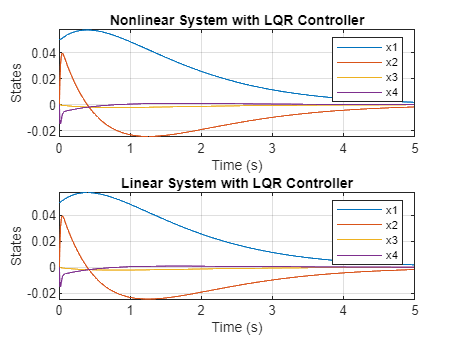


figure;
subplot(2, 1, 1);
plot(t_nonlinear, x_nonlinear);
title('Nonlinear System with LQR Controller');
xlabel('Time (s)');
ylabel('States');
legend('x1', 'x2', 'x3', 'x4');
grid on;

subplot(2, 1, 2);
plot(t_linear, x_linear);
title('Linear System with LQR Controller');
xlabel('Time (s)');
ylabel('States');
legend('x1', 'x2', 'x3', 'x4');
grid on;

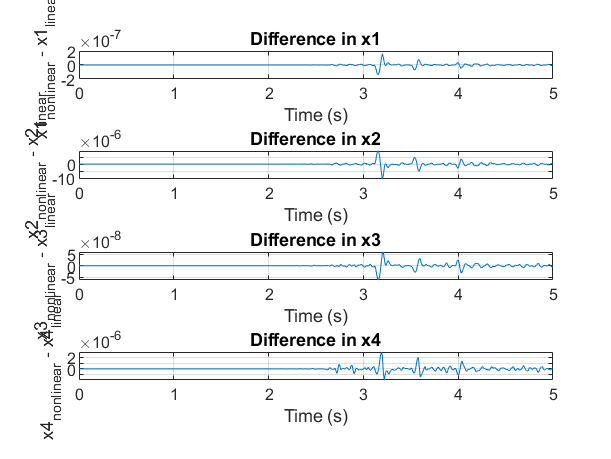


difference = x_nonlinear - interp1(t_linear, x_linear, t_nonlinear);

figure;
subplot(4, 1, 1);
plot(t_nonlinear, difference(:, 1));
title('Difference in x1');
xlabel('Time (s)');
ylabel('x1_{nonlinear} - x1_{linear}');
grid on;

subplot(4, 1, 2);
plot(t_nonlinear, difference(:, 2));
title('Difference in x2');
xlabel('Time (s)');
ylabel('x2_{nonlinear} - x2_{linear}');
grid on;

subplot(4, 1, 3);
plot(t_nonlinear, difference(:, 3));
title('Difference in x3');
xlabel('Time (s)');
ylabel('x3_{nonlinear} - x3_{linear}');
grid on;

subplot(4, 1, 4);
plot(t_nonlinear, difference(:, 4));
title('Difference in x4');
xlabel('Time (s)');
ylabel('x4_{nonlinear} - x4_{linear}');
grid on;

**Question-14 **:  Simulate the main method and approach of the article and compare the results with the performance of the controllers designed in the previous sections.

clear all;
clc;

% System parameters
A = [0 1 0 0;
     0 0 108.7 -112.4;
     0 0 0 1;
     0 -24.96 85.07 0];
B = [0; 13.93; 0; -20.58];
C = eye(4);
D = zeros(4,1);

% Nonlinear dynamics
nonlinear_dynamics = @(t, x, u) [
    x(2);
    108.7*x(3) - 112.4*x(4) + 13.93*u;
    x(4);
    -24.96*x(2) + 85.07*x(3) - 20.58*u
];

% Initial conditions and simulation time
x0 = [0.05; 0; 0; 0];
tspan = 0:0.01:5;

% LQR design
Q = diag([100 1 100 1]); 
R = 1; 

[K,~,~] = lqr(A, B, Q, R);

% Simulate systems
nonlinear_system = @(t, x) nonlinear_dynamics(t, x, -K*x);
[t_nonlinear, x_nonlinear] = ode45(nonlinear_system, tspan, x0)

t_nonlinear =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


x_nonlinear =     0.0500         0         0         0
    0.0504    0.0749   -0.0004   -0.0601
    0.0515    0.1389   -0.0010   -0.0708
    0.0531    0.1808   -0.0017   -0.0636
    0.0550    0.2020   -0.0023   -0.0520
    0.0571    0.2077   -0.0028   -0.0410
    0.0591    0.2031   -0.0031   -0.0323
    0.0611    0.1922   -0.0034   -0.0258
    0.0630    0.1780   -0.0036   -0.0210
    0.0647    0.1622   -0.0038   -0.0175



linear_system = @(t, x) (A - B*K)*x;
[t_linear, x_linear] = ode45(linear_system, tspan, x0)

t_linear =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


x_linear =     0.0500         0         0         0
    0.0504    0.0749   -0.0004   -0.0601
    0.0515    0.1389   -0.0010   -0.0708
    0.0531    0.1808   -0.0017   -0.0636
    0.0550    0.2020   -0.0023   -0.0520
    0.0571    0.2077   -0.0028   -0.0410
    0.0591    0.2031   -0.0031   -0.0323
    0.0611    0.1922   -0.0034   -0.0258
    0.0630    0.1780   -0.0036   -0.0210
    0.0647    0.1622   -0.0038   -0.0175



% Reduced-order observer design
P_desire = [-5 -6 -7];
K_obs = place(A(2:4, 2:4)', A(1, 2:4)', P_desire)'

K_obs =    18.0000
   -0.2038
  -26.8659


L = K_obs

L =    18.0000
   -0.2038
  -26.8659


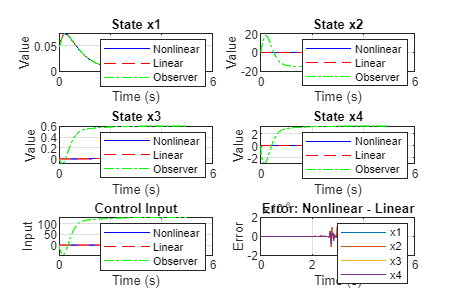


% Simulate reduced-order observer
z = zeros(3, length(tspan));
x_hat = zeros(4, length(tspan));
x_hat(:,1) = x0;
for k = 2:length(tspan)
    y = C * x_nonlinear(k-1, :)';
    x_hat(1,k) = y(1);
    z(:,k) = z(:,k-1) + 0.01 * ((A(2:4,2:4) - L*A(1,2:4))*z(:,k-1) + ...
              (A(2:4,2:4) - L*A(1,2:4))*L*y(1) + A(2:4,1)*y(1) + B(2:4) - L*B(1));
    x_hat(2:4,k) = z(:,k) + L*y(1);
end

% Calculate control inputs
u_nonlinear = -K * x_nonlinear';
u_linear = -K * x_linear';
u_observer = -K * x_hat;


figure('Position', [100, 100, 1200, 800]);

% States
for i = 1:4
    subplot(3,2,i)
    plot(tspan, x_nonlinear(:,i), 'b', t_linear, x_linear(:,i), 'r--', tspan, x_hat(i,:), 'g-.')
    title(['State x' num2str(i)])
    xlabel('Time (s)')
    ylabel('Value')
    legend('Nonlinear', 'Linear', 'Observer')
    grid on
end

% Control inputs
subplot(3,2,5)
plot(tspan, u_nonlinear, 'b', tspan, u_linear, 'r--', tspan, u_observer, 'g-.')
title('Control Input')
xlabel('Time (s)')
ylabel('Input')
legend('Nonlinear', 'Linear', 'Observer')
grid on

% Error between nonlinear and linear
subplot(3,2,6)
plot(tspan, x_nonlinear - x_linear)
title('Error: Nonlinear - Linear')
xlabel('Time (s)')
ylabel('Error')
legend('x1', 'x2', 'x3', 'x4')
grid on


% Performance analysis
settling_time_nl = find(abs(x_nonlinear(:,1) - x_nonlinear(end,1)) < 0.02*abs(x_nonlinear(end,1)), 1) * (tspan(2)-tspan(1));
settling_time_l = find(abs(x_linear(:,1) - x_linear(end,1)) < 0.02*abs(x_linear(end,1)), 1) * (tspan(2)-tspan(1));
settling_time_obs = find(abs(x_hat(1,:) - x_hat(1,end)) < 0.02*abs(x_hat(1,end)), 1) * (tspan(2)-tspan(1));

overshoot_nl = max(abs(x_nonlinear(:,1))) / abs(x_nonlinear(end,1)) - 1;
overshoot_l = max(abs(x_linear(:,1))) / abs(x_linear(end,1)) - 1;
overshoot_obs = max(abs(x_hat(1,:))) / abs(x_hat(1,end)) - 1;

fprintf('Nonlinear System:\n')

Nonlinear System:


fprintf('Settling time: %.2f s\n', settling_time_nl)

Settling time: 5.00 s


fprintf('Overshoot: %.2f%%\n\n', overshoot_nl*100)

Overshoot: 83138.65%




fprintf('Linear System:\n')

Linear System:


fprintf('Settling time: %.2f s\n', settling_time_l)

Settling time: 5.00 s


fprintf('Overshoot: %.2f%%\n\n', overshoot_l*100)

Overshoot: 83143.53%




fprintf('Observer System:\n')

Observer System:


fprintf('Settling time: %.2f s\n', settling_time_obs)

Settling time: 5.00 s


fprintf('Overshoot: %.2f%%\n', overshoot_obs*100)

Overshoot: 81929.06%


## **Functions of all Questions:**

function [A_min, B_min, C_min] = minimal_realization(A, B, C)
    Mc = ctrb(A, B);
    Mo = obsv(A, C);
    
    rank_c = rank(Mc);
    rank_o = rank(Mo);
    
    r = min(rank_c, rank_o);
    
    [U, S, V] = svd(Mc * Mo');
    T = U(:, 1:r);
    
    A_min = T' * A * T;
    B_min = T' * B;
    C_min = C * T;
end
%--------------------------------------------------
% Q-9 fcn:
function dxdt = observer_dynamics(t, x, A, B, C, L, K)
    % Extract the actual state and the estimated state
    n = size(A, 1);
    x_actual = x(1:n);
    x_est = x(n+1:end);
    
    u = 0;
    
    % Actual system dynamics
    dx_actual = A * x_actual + B * u;
    
    % Observer dynamics
    y = C * x_actual;
    y_est = C * x_est;
    dx_est = A * x_est + B * u + L * (y - y_est);
    
    % Combine the dynamics
    dxdt = [dx_actual; dx_est];
end